%Problem 1
%(a)Solving Least Squares
x = [0, 0.5, 1.0, 1.5, 2.0, 2.5]';
y = [0.00, 0.20, 0.27, 0.30, 0.32, 0.33]';
xx = linspace(0, 2.5, 400);
% Fit a polynomial of degree 3 to the data
%% Case (i): use all six points
x1 = x;
y1 = y;

A1 = [x1.^3, x1.^2, x1, ones(size(x1))];
coef1 = A1 \ y1;   % least squares solution

yy1 = coef1(1)*xx.^3 + coef1(2)*xx.^2 + coef1(3)*xx + coef1(4);

%% Case (ii): use points i = 0,1,2,3,4
x2 = x(1:5);
y2 = y(1:5);

A2 = [x2.^3, x2.^2, x2, ones(size(x2))];
coef2 = A2 \ y2;   % least squares solution

yy2 = coef2(1)*xx.^3 + coef2(2)*xx.^2 + coef2(3)*xx + coef2(4);

%% Case (iii): use points i = 0,1,2,3
x3 = x(1:4);
y3 = y(1:4);

A3 = [x3.^3, x3.^2, x3, ones(size(x3))];
coef3 = A3 \ y3;   % exact solution here, since A3 is 4x4

yy3 = coef3(1)*xx.^3 + coef3(2)*xx.^2 + coef3(3)*xx + coef3(4);
% Display all coefficients
disp(coef1)

    0.0511
   -0.2738
    0.4970
    0.0033



disp(coef2)

    0.0800
   -0.3543
    0.5486
    0.0009



disp(coef3)

    0.1200
   -0.4400
    0.5900
         0




%Problem 3
%b)
% different numbers of interpolation nodes
Nvals = [4, 6, 12, 16,32,64];

xx = linspace(0,1,1000);

% define the step function on the plotting grid
fxx = double(xx > 0.5);

figure;

for k = 1:length(Nvals)
    N = Nvals(k);

    % uniformly spaced interpolation nodes in (0,1)
    alpha = linspace(0,1,N+2);
    alpha = alpha(2:end-1);   % remove endpoints, keep points in (0,1)

    % function values at interpolation nodes
    y = double(alpha > 0.5);

    % interpolation polynomial of degree <= N-1
    pcoef = polyfit(alpha, y, N-1);
    pxx = polyval(pcoef, xx);

    subplot(2,3,k)
    plot(xx, fxx, 'r--', 'LineWidth', 1.5); hold on;
    plot(xx, pxx, 'b-', 'LineWidth', 1.5);
    plot(alpha, y, 'ro', 'MarkerSize', 5, 'LineWidth', 1.2);
    title(['N = ', num2str(N), ' interpolation nodes'])
  
    ylim([-0.5, 1.5])
    grid on
end

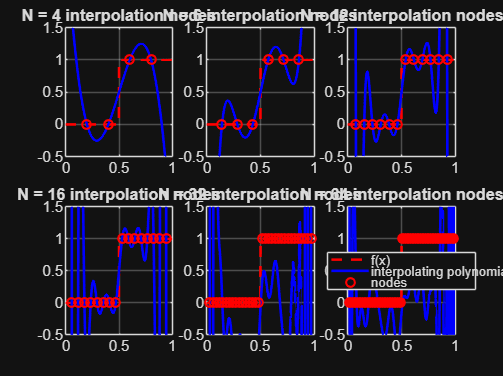

legend('f(x)', 'interpolating polynomial', 'nodes', 'Location', 'best')


%d)
% values of n required in part (d)
nvals = [4, 8, 12, 16, 32, 64];

% plotting grid
xx = linspace(0,1,2000);

% exact solution from part (c)
uexact = zeros(size(xx));
idx1 = (xx <= 0.5);
idx2 = (xx > 0.5);

uexact(idx1) = (1/8) * xx(idx1);
uexact(idx2) = -(xx(idx2).^2)/2 + (5/8)*xx(idx2) - 1/8;

figure;

for k = 1:length(nvals)
    n = nvals(k);

    % uniformly spaced interpolation nodes in (0,1)
    alpha = linspace(0,1,n+2);
    alpha = alpha(2:end-1);

    % values of f at the interpolation nodes
    y = double(alpha > 0.5);

    % interpolating polynomial p_n of degree <= n-1
    % (using n nodes)
    pcoef = polyfit(alpha, y, n-1);

    % We want to solve: -u_n'' = p_n
    % so u_n'' = -p_n

    % integrate twice
    qcoef = -pcoef;                 % coefficients of u_n''
    ucoef = polyint(polyint(qcoef));% coefficients of general solution

    % after two integrations, MATLAB sets the constants to zero
    % so currently this is only a particular solution.
    % Add linear term A*x + B:
    %
    % u_n(x) = polyval(ucoef,x) + A*x + B
    %
    % Use boundary conditions:
    % u_n(0)=0, u_n(1)=0

    % evaluate the particular solution at x=0 and x=1
    u0 = polyval(ucoef, 0);
    u1 = polyval(ucoef, 1);

    % Solve for A and B:
    % u0 + B = 0
    % u1 + A + B = 0
    B = -u0;
    A = -(u1 + B);

    % evaluate numerical solution on the grid
    unum = polyval(ucoef, xx) + A*xx + B;

    % plot
    subplot(3,2,k)
    plot(xx, uexact, 'r--', 'LineWidth', 1.8); hold on;
    plot(xx, unum, 'b-', 'LineWidth', 1.5);
    title(['n = ', num2str(n)])
    legend('exact solution', 'polynomial solution u_n', 'Location', 'best')
    grid on
end

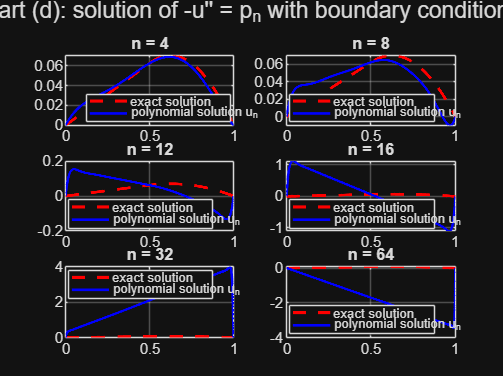


sgtitle('Part (d): solution of -u'''' = p_n with boundary conditions')

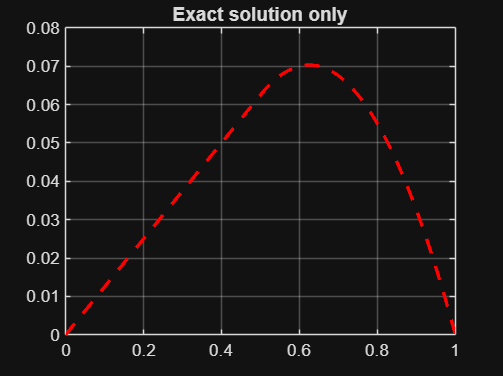


figure;
plot(xx, uexact, 'r--', 'LineWidth', 2);
title('Exact solution only')
grid on

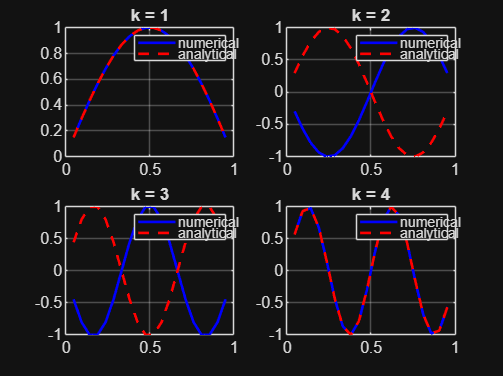


%Problem 4
%(e)
N = 20;                 % choose N >= 20
h = 1/(N+1);

% Step 1: build matrix K
e = ones(N,1);
K = (1/h^2)*(diag(2*e) - diag(e(1:end-1),1) - diag(e(1:end-1),-1));

% Step 2: compute eigenvalues and eigenvectors
[V,D] = eig(K);

% sort eigenvalues (important!)
[lambda, idx] = sort(diag(D));
V = V(:,idx);

% grid points
x = (1:N)' * h;

% Step 3: compare with analytical eigenvectors
figure;

for k = 1:4   % plot first 4 modes
    
    subplot(2,2,k)
    
    % numerical eigenvector
    v_num = V(:,k);
    
    % analytical eigenvector
    v_exact = sin(k*pi*x);
    
    % normalize both (so they match visually)
    v_num = v_num / max(abs(v_num));
    v_exact = v_exact / max(abs(v_exact));
    
    plot(x, v_num, 'b-', 'LineWidth', 1.5); hold on;
    plot(x, v_exact, 'r--', 'LineWidth', 1.5);
    
    title(['k = ', num2str(k)])
    legend('numerical', 'analytical')
    grid on
end

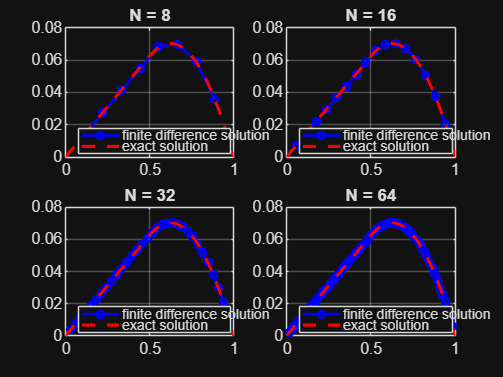


%(f)
Nvals = [8, 16, 32, 64];

figure;

for k = 1:length(Nvals)
    N = Nvals(k);
    h = 1/(N+1);

    % interior grid points
    x = (1:N)' * h;

    % right-hand side f(x_i)
    fvec = double(x > 0.5);

    % build tridiagonal matrix K
    e = ones(N,1);
    K = (1/h^2) * (diag(2*e) - diag(e(1:end-1),1) - diag(e(1:end-1),-1));

    % solve K u = f
    u = K \ fvec;

    % plot numerical solution
    subplot(2,2,k)
    plot(x, u, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 4); hold on;

    % exact solution for comparison
    xx = linspace(0,1,1000);
    uexact = zeros(size(xx));
    idx1 = (xx <= 0.5);
    idx2 = (xx > 0.5);

    uexact(idx1) = (1/8)*xx(idx1);
    uexact(idx2) = -(xx(idx2).^2)/2 + (5/8)*xx(idx2) - 1/8;

    plot(xx, uexact, 'r--', 'LineWidth', 1.8);

    title(['N = ', num2str(N)])
    legend('finite difference solution', 'exact solution', 'Location', 'best')
    grid on
end

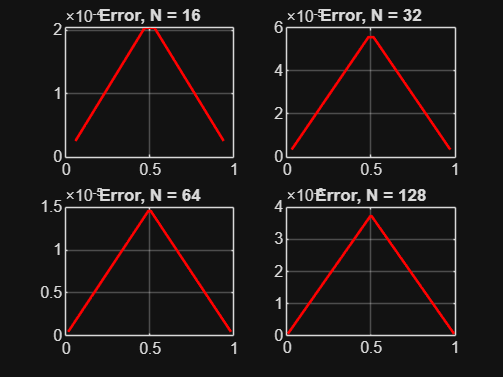


%(g)
Nvals = [16, 32, 64, 128];
errors = zeros(size(Nvals));

figure;

for k = 1:length(Nvals)
    N = Nvals(k);
    h = 1/(N+1);

    % grid
    x = (1:N)' * h;

    % RHS f
    fvec = double(x > 0.5);

    % build K
    e = ones(N,1);
    K = (1/h^2)*(diag(2*e) - diag(e(1:end-1),1) - diag(e(1:end-1),-1));

    % solve
    u = K \ fvec;

    % exact solution
    uexact = zeros(size(x));
    idx1 = (x <= 0.5);
    idx2 = (x > 0.5);

    uexact(idx1) = (1/8)*x(idx1);
    uexact(idx2) = -(x(idx2).^2)/2 + (5/8)*x(idx2) - 1/8;

    % error
    err = abs(uexact - u);
    errors(k) = max(err);

    % plot error
    subplot(2,2,k)
    plot(x, err, 'r-', 'LineWidth', 1.5)
    title(['Error, N = ', num2str(N)])
    grid on
end

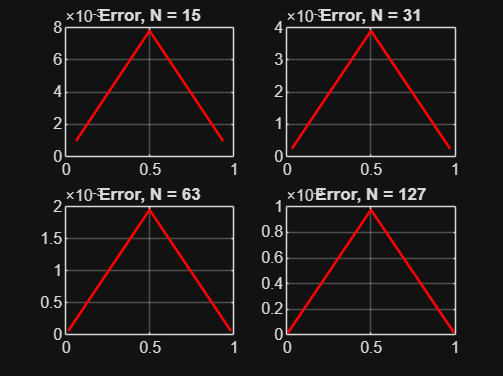


Nvals = [15, 31, 63, 127];
errors = zeros(size(Nvals));

figure;

for k = 1:length(Nvals)
    N = Nvals(k);
    h = 1/(N+1);

    % grid
    x = (1:N)' * h;

    % RHS f
    fvec = double(x > 0.5);

    % build K
    e = ones(N,1);
    K = (1/h^2)*(diag(2*e) - diag(e(1:end-1),1) - diag(e(1:end-1),-1));

    % solve
    u = K \ fvec;

    % exact solution
    uexact = zeros(size(x));
    idx1 = (x <= 0.5);
    idx2 = (x > 0.5);

    uexact(idx1) = (1/8)*x(idx1);
    uexact(idx2) = -(x(idx2).^2)/2 + (5/8)*x(idx2) - 1/8;

    % error
    err = abs(uexact - u);
    errors(k) = max(err);

    % plot error
    subplot(2,2,k)
    plot(x, err, 'r-', 'LineWidth', 1.5)
    title(['Error, N = ', num2str(N)])
    grid on
end